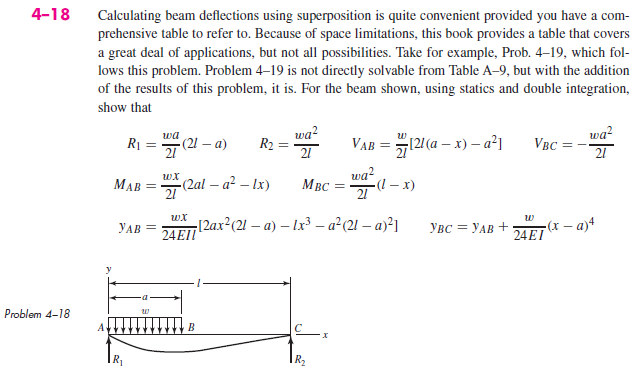

# symbolic units class

u = symunit;

# assumptions

old_assum = assumptions;
clearassum;

# given

wo = sym('wo');
a = sym('a');
L = sym('L');
assume(0 < a & a < L);

# beam

b = beam;
b = b.add('reaction', 'force', 'R1', 0);
b = b.add('reaction', 'force', 'R2', L);
b = b.add('distributed', 'force', -wo, [0 a]);

# elastic curve

[y dy m v w r] = b.elastic_curve([], 'factor'); %#ok
y

$$y(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,x\,\left(4\,L^{2}\,a^{2}-4\,L\,a^{3}-4\,L\,a\,x^{2}+L\,x^{3}+a^{4}+2\,a^{2}\,x^{2}\right)}{24\,\text{E}\,\text{I}\,L} & \text{ if }x\leq a\\ \frac{a^{2}\,\mathrm{wo}\,\left(L-x\right)\,\left(a^{2}+2\,x^{2}-4\,L\,x\right)}{24\,\text{E}\,\text{I}\,L} & \text{ if }a<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,\left(4\,L^{2}\,a^{2}-4\,L\,a^{3}-12\,L\,a\,x^{2}+4\,L\,x^{3}+a^{4}+6\,a^{2}\,x^{2}\right)}{24\,\text{E}\,\text{I}\,L} & \text{ if }x\leq a\\ -\frac{a^{2}\,\mathrm{wo}\,\left(4\,L^{2}-12\,L\,x+a^{2}+6\,x^{2}\right)}{24\,\text{E}\,\text{I}\,L} & \text{ if }a<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,x\,\left(a^{2}-2\,L\,a+L\,x\right)}{2\,L} & \text{ if }x\leq a\\ \frac{a^{2}\,\mathrm{wo}\,\left(L-x\right)}{2\,L} & \text{ if }a<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,\left(a^{2}-2\,L\,a+2\,L\,x\right)}{2\,L} & \text{ if }x\leq a\\ -\frac{a^{2}\,\mathrm{wo}}{2\,L} & \text{ if }a<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -\mathrm{wo} & \text{ if }x\leq a\\ 0 & \text{ if }a<x \end{array}\right.$$

addvar(y);

# reactions

R1 = r.R1 %#ok

$$R1 = \frac{a\,\mathrm{wo}\,\left(2\,L-a\right)}{2\,L}$$

R2 = r.R2 %#ok

$$R2 = \frac{a^{2}\,\mathrm{wo}}{2\,L}$$

clear R1 R2;

# shear and moment diagram

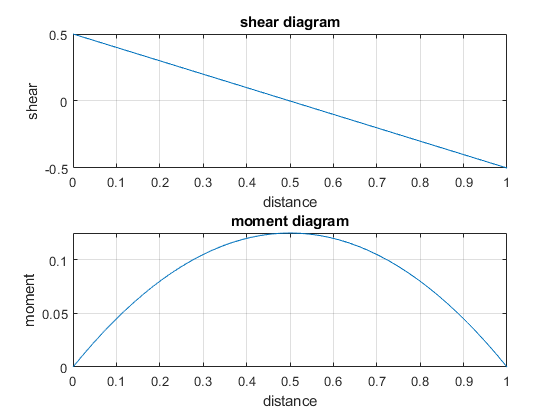

beam.shear_moment(m, v, [0 1], [wo a L], 1);

setassum(old_assum);
clear old_assum;